%METODO ALGEBRAICO, JHON PARRA
clear all,clc
%Ingresar funciones de transferencia manualmente para no variar G
%Funcion de transferencia con tiempo muerto , aplicar PADE
s=tf('s');
G=(266.2)/((s+10.53)*(s+5.356)*(s+4.069))

G =
 
               266.2
  -------------------------------
  s^3 + 19.95 s^2 + 121 s + 229.5
 
Continuous-time transfer function.



%G=(50)/(s+5)^2
%G=(10)/((s+5)*(s+2))
%G=(1)/((s+2)*(s+1))
%G=(1)/(s*(s+4))
%G=(10)/(s^2-s)
%G=(10)/(s*(s-1)*(s+2))
%G=(2*exp(-0.2*s))/(s*(s+4));G=pade(G)
%G=(2)/(s*(s+2))
%G=(10)/(s^2+(7*s)+10)
%G=((18.112*s)+(54.337))/(s^3+4.089*s^2+17.682*s+54.337)
%G=(10)/(s^2+(7*s)+10)
%G=(2)/((0.1*s+1)*(0.25*s+1))
%G=(132.16)/((s+4.027)*(s+16.07))
%G=(exp(-0.5*s))/((s+2))
%G=2.024/(0.02592*s^2+0.7834*s+1) %JAIR NAVARRO
%G=(2.027)/((0.0546*s^2)+(0.8225*s)+1)
%G=2.026/(0.03967*s^2+0.7961*s+1)
%G=(2.027)/((0.0546*s^2)+(0.8225*s)+1) %Jhon
%G=2.026/(0.03967*s^2+0.7961*s+1)
%G=(2.035)/ ((0.1353*s^2) + (1.001*s )+ 1)%jhon real
%G=(2.032)/((0.1107*s^2)+(1.006*s)+ 1)
%G=zpk([],[-7.509 -1.419],[21.589]) %vera
%G=(2.029)/((0.1115*s^2)+(0.9406*s)+ 1) %kempys
%G=2.029/(0.05522*s^2+0.8221*s+1)
[nn,dd] = tfdata(G,'v');
n = length(dd)-1;
m = n-1;
fprintf('Orden minimo controlador: %u \r\n',m) 

Orden minimo controlador: 2 


n = input('Ingrese orden del controlador: ');
fprintf('Número de polos: %u \r\n',m+n+1) 

Número de polos: 4 


polosDeseados = input('Ingrese los polos deseados: Ej [-1 -5 -2+i -2-i]')

polosDeseados =    -10   -10   -10   -10


modelo = poly(polosDeseados)'

modelo =            1
          40
         600
        4000
       10000


modelo_polinomio = tf(modelo',1)

modelo_polinomio =
 
  s^4 + 40 s^3 + 600 s^2 + 4000 s + 10000
 
Continuous-time transfer function.



vPole = [];
vZero = [];
for i=0:1:n
    xn=padarray(dd,[0,i],0,'pre');
    xn=padarray(xn,[0,n-i],0,'pos');
    vPole = [vPole xn'];
    
    xn=padarray(nn,[0,i],0,'pre');
    xn=padarray(xn,[0,n-i],0,'pos');
    vZero = [vZero xn'];
end
A=[vPole vZero] 

A =     1.0000         0         0         0
   19.9550    1.0000         0         0
  121.0388   19.9550         0         0
  229.4862  121.0388  266.2000         0
         0  229.4862         0  266.2000


vecColDel = [];
if n>m 
    fprintf('Como escogio un controlador de orden %u debe eliminar %u columna(s) de la matriz\r\n',n,n-m)
    disp('Nota: Elimine columnas en orden de la menor a la mayor.')
    for i=1:1:n-m
        colDel = input('Ingrese número de columna a eliminar: ej: 3: ');
        vecColDel = [vecColDel,colDel];
        A(:,colDel-i+1) = [];
    end
end
Sol=(A\modelo)';
lenVecColDel = length(vecColDel);
for i=1:1:lenVecColDel
    vecSol1 = Sol(1:vecColDel(i)-1);
    vecSol2 = Sol(vecColDel(i):end);
    Sol = [vecSol1 0 vecSol2];
end
len = length(Sol);
den = Sol(1:len/2);
num = Sol(len/2+1:end);
disp('Controlador: ')

Controlador: 


C = tf(num,den)

C =
 
  2.713 s + 15.39
  ----------------
  0.7166 s + 25.72
 
Continuous-time transfer function.



disp('Modelo: ')

Modelo: 


Tc = feedback(G*C,1)

Tc =
 
                   722.3 s + 4097
  -------------------------------------------------
  0.7166 s^4 + 40.02 s^3 + 600 s^2 + 4000 s + 10000
 
Continuous-time transfer function.



disp('Polos modelo: ')

Polos modelo: 


polosModelo = pole(Tc)

polosModelo =  -37.0365 + 0.0000i
  -6.5196 + 4.7701i
  -6.5196 - 4.7701i
  -5.7739 + 0.0000i


F=1/dcgain(Tc)

F = 2.4406

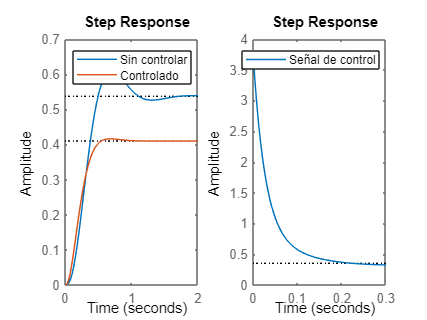

Tk = feedback(G,1);
Suk = feedback(C,G);
subplot(121),step(Tk,Tc), legend('Sin controlar','Controlado')

subplot(122),step(Suk), legend('Señal de control')